% Boedo and Prantil 1998: corrected solution of clamped ring plate with edge point load
% https://ascelibrary.org/doi/epdf/10.1061/%28ASCE%290733-9399%281998%29124%3A6%28696%29

## Comparison against Boedo paper

N = 100;

lam = 2/3;
nu = 0.3;

theta = 0:pi/8:pi;
rho = 2/3;
[w_normalized,Mr_normalized,abcd] = calc_plate(lam,nu,theta,rho,N);

format shortE
abcd(1:10,:)

ans =   -2.4628e-01   2.6060e-01  -2.1064e-01  -2.5000e-01
   5.6862e-02  -1.1715e-01   8.7971e-02   5.0000e-01
   1.4973e-01  -3.6700e-02   2.3133e-02  -1.1135e-01
   5.9034e-02  -1.8376e-02   8.2143e-03  -2.8530e-02
   3.3377e-02  -1.1777e-02   3.0900e-03  -9.4233e-03
   2.1425e-02  -8.5354e-03   1.1572e-03  -3.2917e-03
   1.4625e-02  -6.5209e-03   4.2958e-04  -1.1699e-03
   1.0416e-02  -5.1113e-03   1.5962e-04  -4.2191e-04
   7.6881e-03  -4.0805e-03   5.9845e-05  -1.5477e-04
   5.8546e-03  -3.3123e-03   2.2727e-05  -5.7808e-05


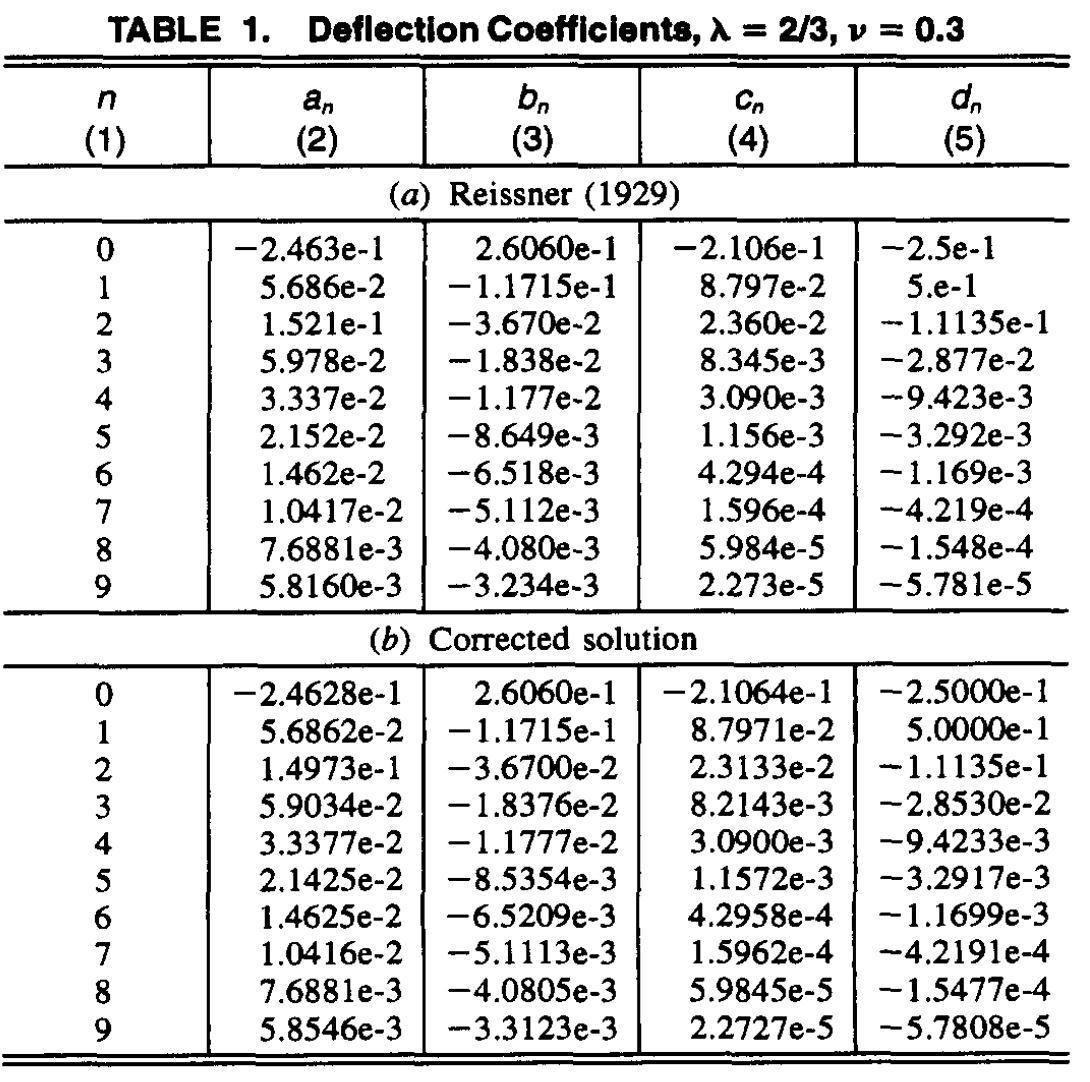

Mr_normalized'

ans =   -4.4222e+00
  -1.4283e+00
  -2.3439e-02
   4.5735e-02
   8.4898e-03
  -7.6379e-05
  -2.9049e-04
  -4.4280e-05
   3.6329e-06


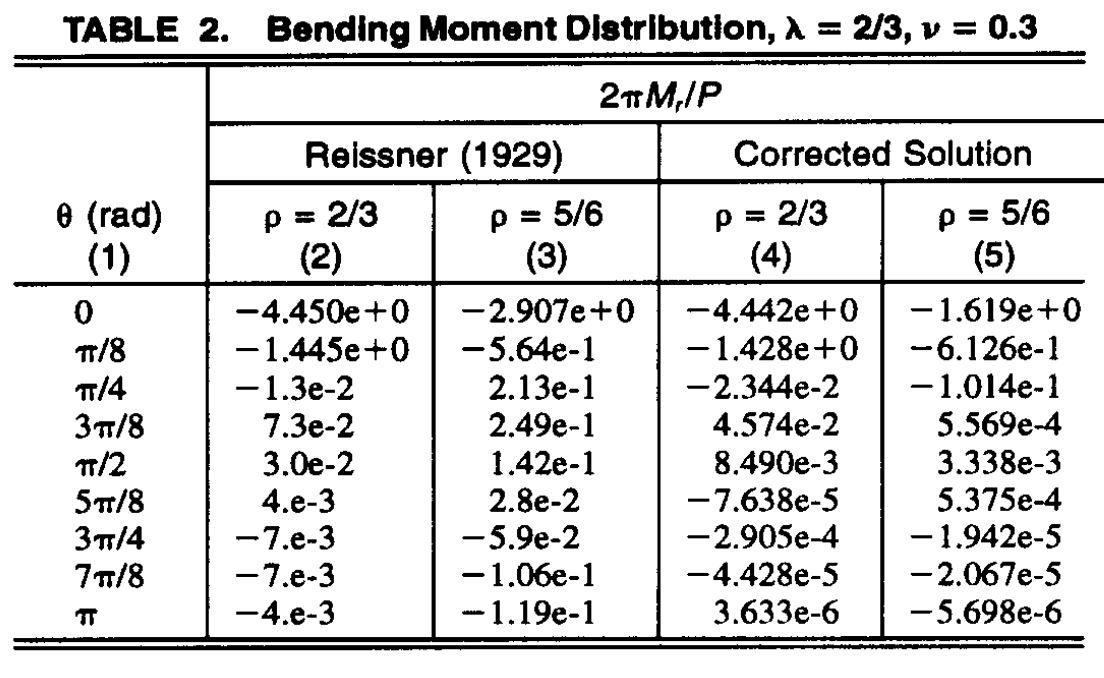

sigma_normalized = 3/pi * abs(Mr_normalized(1))

sigma_normalized =    4.2229e+00


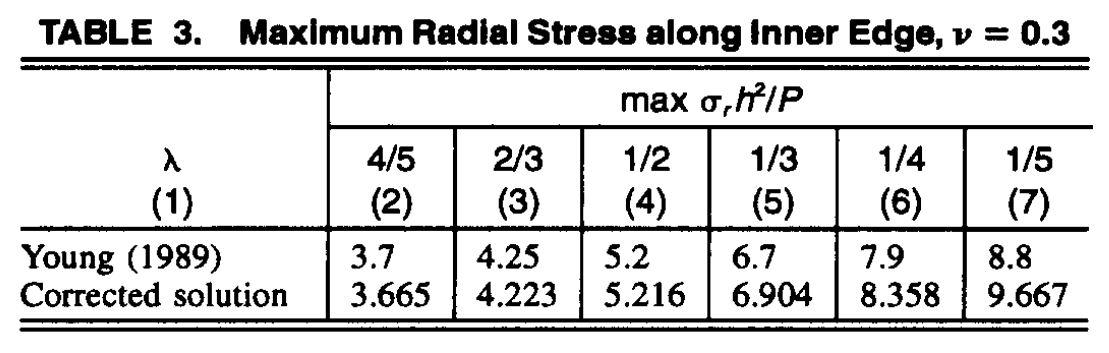

## Plot deflection

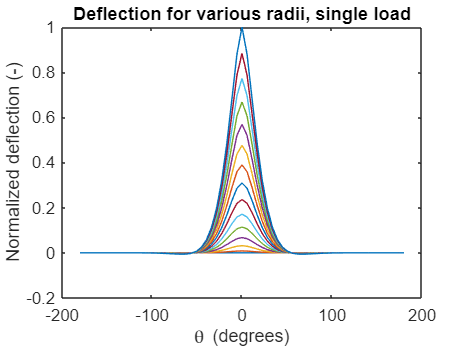

theta = 0:pi/32:pi;
rho = linspace(lam,1,15);
[w_normalized,Mr_normalized] = calc_plate(lam,nu,theta,rho,N);

% currently plotting deflection at point of max stress, which is inner
% edge, so deflection is supposed to be zero!
format default
figure
theta_full = [fliplr(-theta) theta];
w_full = [fliplr(w_normalized) w_normalized]/max(w_normalized,[],'all');
plot(180/pi*theta_full, w_full)
xlabel('\theta (degrees)')
ylabel('Normalized deflection (-)')
title('Deflection for various radii, single load')

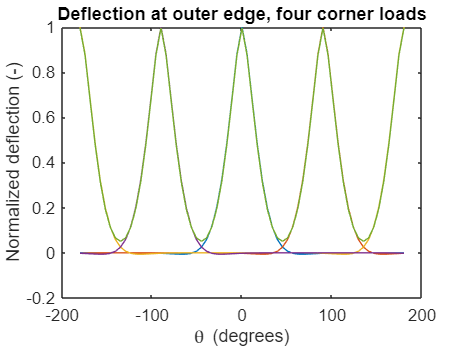


[theta_0,w_0]     = shift(theta_full,w_full,0);
[theta_90,w_90]   = shift(theta_full,w_full,pi/2);
[theta_180,w_180] = shift(theta_full,w_full,pi);
[theta_270,w_270] = shift(theta_full,w_full,3*pi/2);

% max deflection occurs at outer edge 
w_0_max = w_0(end,:); 
w_90_max = w_90(end,:); 
w_180_max = w_180(end,:); 
w_270_max = w_270(end,:); 

figure
plot(180/pi*theta_0,w_0_max)
hold on
plot(180/pi*theta_90,w_90_max)
plot(180/pi*theta_180,w_180_max)
plot(180/pi*theta_270,w_270_max)
plot(180/pi*theta_0, w_0_max+w_90_max+w_180_max+w_270_max)
xlabel('\theta (degrees)')
ylabel('Normalized deflection (-)')
title('Deflection at outer edge, four corner loads')

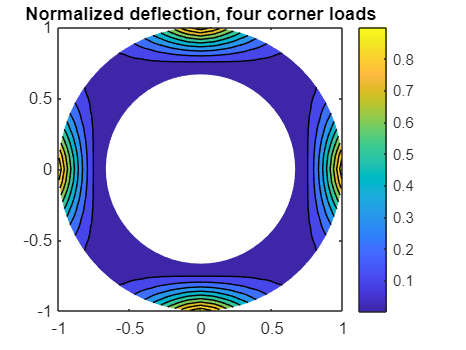


figure
x = rho'*cos(theta_0);
y = rho'*sin(theta_0);
z = w_0 + w_90 + w_180 + w_270;
contourf(x,y,z)
colorbar
axis equal
title('Normalized deflection, four corner loads')

## Max stress

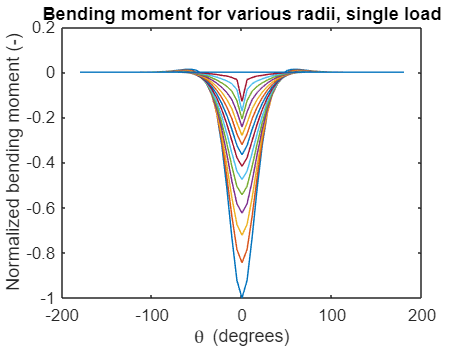


figure
theta_full = [fliplr(-theta) theta];
Mr_full = [fliplr(Mr_normalized) Mr_normalized]/max(abs(Mr_normalized),[],'all');
plot(180/pi*theta_full, Mr_full)
xlabel('\theta (degrees)')
ylabel('Normalized bending moment (-)')
title('Bending moment for various radii, single load')

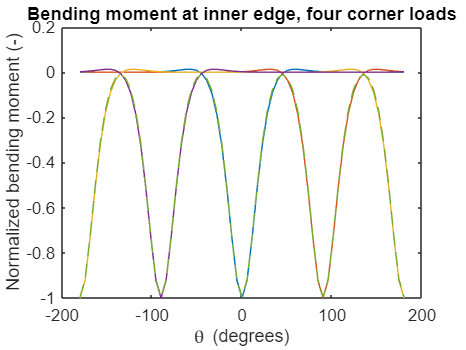


[theta_0,Mr_0] = shift(theta_full,Mr_full,0);
[theta_90,Mr_90] = shift(theta_full,Mr_full,pi/2);
[theta_180,Mr_180] = shift(theta_full,Mr_full,pi);
[theta_270,Mr_270] = shift(theta_full,Mr_full,3*pi/2);

% max stress occurs at inner edge
Mr_0_max   = Mr_0(1,:); 
Mr_90_max  = Mr_90(1,:); 
Mr_180_max = Mr_180(1,:); 
Mr_270_max = Mr_270(1,:); 

figure
plot(180/pi*theta_0,Mr_0_max)
hold on
plot(180/pi*theta_90,Mr_90_max)
plot(180/pi*theta_180,Mr_180_max)
plot(180/pi*theta_270,Mr_270_max)
plot(180/pi*theta_0, Mr_0_max+Mr_90_max+Mr_180_max+Mr_270_max,'--')
xlabel('\theta (degrees)')
ylabel('Normalized bending moment (-)')
title('Bending moment at inner edge, four corner loads')

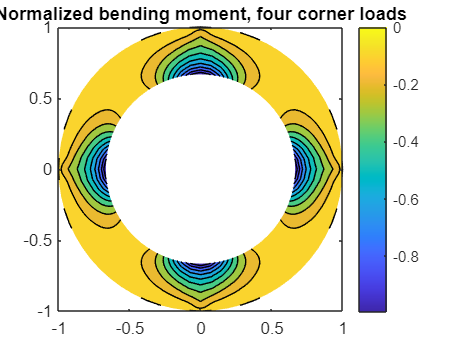


figure
z = Mr_0 + Mr_90 + Mr_180 + Mr_270;
contourf(x,y,z)
colorbar
axis equal
title('Normalized bending moment, four corner loads')

## Validate RM3 report


b = 3; % inner radius
a = 15; % outer radius
lam = b/a;

## functions

function [theta_shift,x_shift] = shift(theta, x, delta_theta)
% fixme: if I wanted to make a contour plot of deflection or Mr over a
% theta/rho mesh, I need to fix this function to accept matrix inputs for x
    theta_shift = wrapToPi(theta + delta_theta);
    [theta_shift,sort_idx] = sort(theta_shift);
    [theta_shift,unique_idx] = unique(theta_shift);
    sort_idx = sort_idx(unique_idx);
    x_shift = x(:,sort_idx);

    % add start point that equals end point
    if theta_shift(1)+2*pi ~= theta_shift(end)
        theta_shift = [theta_shift(end)-2*pi theta_shift];
        x_shift = [x_shift(:,end) x_shift];
    end
end

function [w_normalized,Mr_normalized,abcd] = calc_plate(lam,nu,theta,rho,N)
    assert(isscalar(lam))
    assert(isscalar(nu))
    assert(isscalar(N))
    % vector inputs only allowed for theta and rho

    [RHO,n] = meshgrid(rho,2:N);
    d0 = -1/4;
    c0_num = (1 + 2*log(lam)) * (1+nu) - (3+nu);
    c0_den = lam^(-1)*(1+nu) + lam*(1-nu);
    c0 = lam/4 * c0_num / c0_den;
    b0 = c0/2 * (1-nu)/(1+nu) + (3+nu)/(8*(1+nu));
    a0 = -lam^2*b0 - c0*log(lam) - d0*lam^2*log(lam);
    
    d1 = 1/2;
    b1 = -1/4 * (1+nu+lam^2*(1-nu)) / (3+nu+lam^4*(1-nu));
    c1 = -b1*(3+nu)/(1-nu) - 1/4 * (1+nu)/(1-nu);
    a1 = -b1*lam^2 - c1*lam^(-2) - d1*log(lam);
    
    A = (3+nu)/(1-nu);
    B = (1-lam^2)^2 * (n.^2-1) + (lam.^(-2*n+2)+A) .* (lam.^(2*n+2)+A);
    
    dn_num = (1-lam^2)*(n-1) + lam.^( 2*n+2) + A;
    bn_num = (1-lam^2)*(n+1) - lam.^(-2*n+2) - A;
    dn_denom = B.*n.*(n-1)*(1-nu);
    bn_denom = B.*n.*(n+1)*(1-nu);
    dn = -dn_num ./ dn_denom;
    bn =  bn_num ./ bn_denom;
    an = -lam^2 * (bn .* (n+1)./n + dn .* lam.^(-2*n)./n);
    cn = -lam^2 * (dn .* (n-1)./n - bn .* lam.^( 2*n)./n);
    
    if length(rho)==1
    abcd  = [a0 b0 c0 d0;
             a1 b1 c1 d1;
             an bn cn dn];
    end
    
    Rho_zero_terms = a0 + b0 * rho.^2 + c0 * log(rho) + d0 * rho.^2 .* log(rho);
    Rho_one_terms = a1*rho + b1 * rho.^3 + c1 * rho.^(-1) + d1 * rho .* log(rho);

    
    Rho_two_to_N_terms = an .* RHO.^n + bn .* RHO.^(n+2) + cn .* RHO.^(-n) + dn .* RHO.^(-n+2);
    
    w_normalized = Rho_zero_terms' + Rho_one_terms' * cos(theta) + Rho_two_to_N_terms' * cos(n(:,1)*theta);
    
    e0_d0_coeff = 3 + nu + 2*(1+nu)*log(rho);
    e0 = 2*b0*(1+nu) - c0*rho.^-2*(1-nu) + d0*(e0_d0_coeff);
    e1 = 2*b1*rho*(3+nu) + 2*c1*rho.^-3*(1-nu) + d1*rho.^-1*(1+nu);
    
    en_a_term = an .* RHO.^(n-2) .* n .* (n-1) * (1 - nu);
    en_b_term = bn .* RHO.^n .* (n+1) .* (n + 2 - nu*(n-2));
    en_c_term = cn .* RHO.^(-n-2) .* n .* (n+1) * (1-nu);
    en_d_term = dn .* RHO.^-n .* (n-1) .* (n-2 - nu*(n+2));
    en = en_a_term + en_b_term + en_c_term + en_d_term;
    Mr_normalized = -1 * (e0' + e1'*cos(theta) + en'*cos(n(:,1)*theta));
end